function [a, b] = aproximarePade(f, m, k)
    n = m + k;
    syms x

 
    c = zeros(1, n + 1);
    for i = 0:n
        deriv = diff(f, x, i);
        c(i+1) = double(subs(deriv, x, 0)) / factorial(i);
    end

   
    if k > 0 
        C_matrice = zeros(k, k);
        y_vec = zeros(k, 1);

        for i = 1:k
            for j = 1:k
                id = m + i - j;
                if id >= 0 && id <= n
                    C_matrice(i, j) = c(id + 1);
                end
            end
           
            y_vec(i) = -c(m + i + 1);
        end
        
        b_rest = C_matrice \ y_vec;
        b = [1; b_rest];
    else
        b = 1;
    end

    a = zeros(m + 1, 1);
    for j = 0:m
        for l = 0:min(j, k)

            a(j + 1) = a(j + 1) + c(j - l + 1) * b(l + 1);
        end
    end
end

syms x
f = exp(x)

$$f = {\mathrm{e}}^{x}$$

interval = linspace(-1, 1, 100)

interval =    -1.0000   -0.9798   -0.9596   -0.9394   -0.9192   -0.8990   -0.8788   -0.8586   -0.8384   -0.8182   -0.7980   -0.7778   -0.7576   -0.7374   -0.7172   -0.6970   -0.6768   -0.6566   -0.6364   -0.6162   -0.5960   -0.5758   -0.5556   -0.5354   -0.5152   -0.4949   -0.4747   -0.4545   -0.4343   -0.4141   -0.3939   -0.3737   -0.3535   -0.3333   -0.3131   -0.2929   -0.2727   -0.2525   -0.2323   -0.2121   -0.1919   -0.1717   -0.1515   -0.1313   -0.1111   -0.0909   -0.0707   -0.0505   -0.0303   -0.0101


[a,b] = aproximarePade(f,1,1)

a =     1.0000
    0.5000


b =     1.0000
   -0.5000


[a1,b1]= aproximarePade(f,2,2)

a1 =     1.0000
    0.5000
    0.0833


b1 =     1.0000
   -0.5000
    0.0833


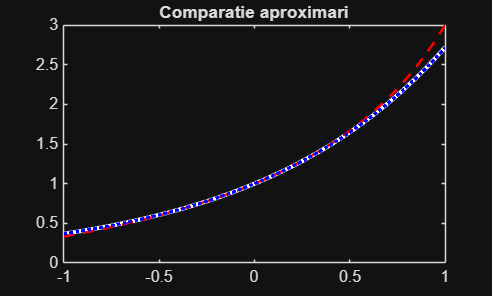


y_real = exp(interval);


y_Pade11 = polyval(flip(a), interval) ./ polyval(flip(b), interval);


y_Pade22 = polyval(flip(a1), interval) ./ polyval(flip(b1), interval);


figure;
plot(interval, y_real, 'w', 'LineWidth', 2.5); 
hold on; 
plot(interval, y_Pade11, 'r--', 'LineWidth', 1.5); 
plot(interval, y_Pade22, 'b:', 'LineWidth', 2);   
title("Comparatie aproximari")



g = log(x+1)

$$g = \log\left(x+1\right)$$

[a2,b2] = aproximarePade(g,2,2)

a2 =          0
    1.0000
    0.5000


b2 =     1.0000
    1.0000
    0.1667


[a22,b22]=aproximarePade(g,3,1)

a22 =          0
    1.0000
    0.2500
   -0.0417


b22 =     1.0000
    0.7500


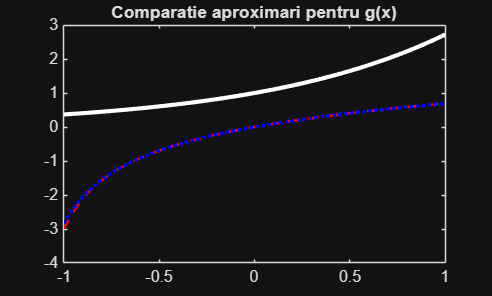


y_Pade11_g = polyval(flip(a2), interval) ./ polyval(flip(b2), interval);
y_Pade22_g = polyval(flip(a22), interval) ./ polyval(flip(b22), interval);

figure;
plot(interval, y_real, 'w', 'LineWidth', 2.5); 
hold on; 
plot(interval, y_Pade11_g, 'r--', 'LineWidth', 1.5); 
plot(interval, y_Pade22_g, 'b:', 'LineWidth', 2);   
title("Comparatie aproximari pentru g(x)");